## IMPORT LIBRARY

addpath('/Users/simone/Documents/MATLAB/R1/LIBRARY/')
savepath /Users/simone/Documents/MATLAB/R1/LIBRARY/pathdef.m

# TRAJECTORY PLANNING IN CARTESIAN SPACE

#### LINEAR PATH

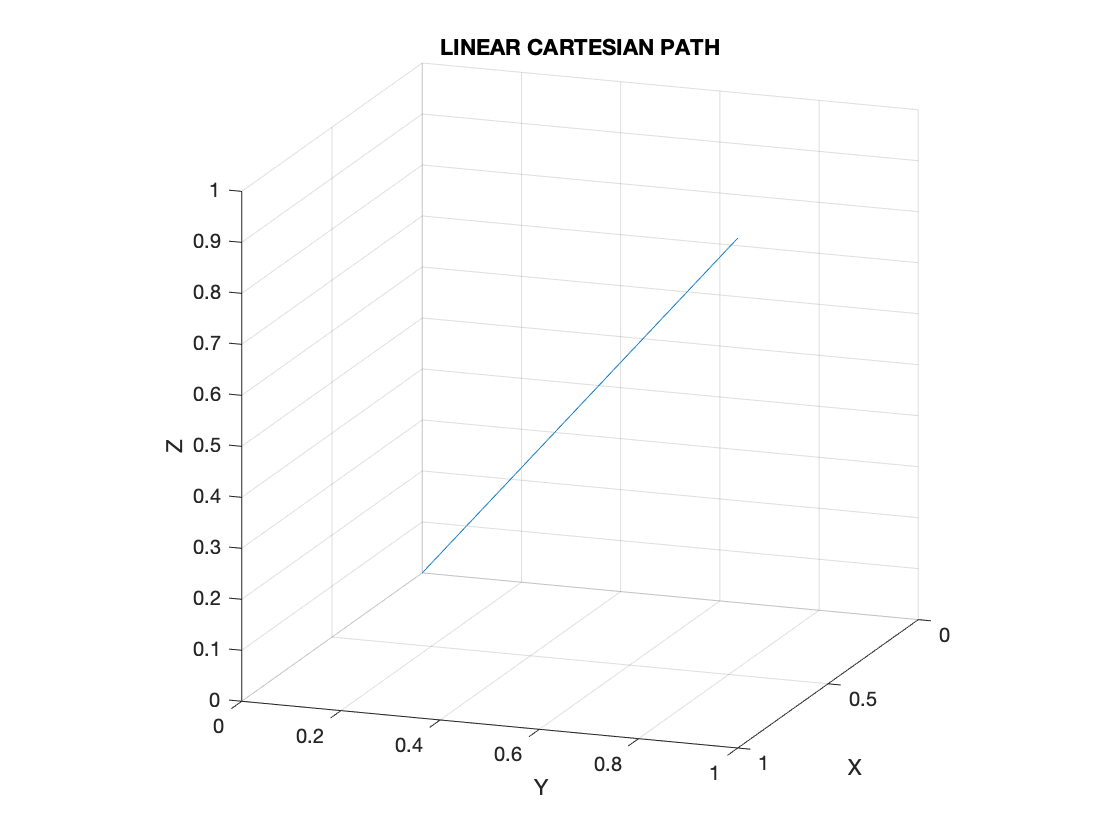

% if t=[start,end]=[0,1] -> s(t)=t

% enlarging the duration reduces the desired VELOCITY
% of a factor of T

% anlarging the duration reduces the desired ACCELERATION
% of a factor of T^2

% changing T -> out velocity p_dot_0/T, out acceleration p_ddot_0/T^2
% thus:
% p_dot = p_dot_desired * T
% p_ddot = p_ddot_desired * T^2

start_line=0;
end_line=1;
T = end_line-start_line;

line_step=0.01;
num_steps=T/line_step;
line_vector = line_step * [start_line:num_steps]';

[p0, p1] = deal([0 0 0]', [1 1 1]');

linear_traj = zeros(length(line_vector),3);

s_vector = line_vector ./ T;

% TRAJECTORY
for s=1:length(s_vector)
    linear_traj(s,:) = SR_ROBO.ptp_linear(p0, p1,s_vector(s))';
end

plot3(linear_traj(:,1),linear_traj(:,2),linear_traj(:,3))
title('LINEAR CARTESIAN PATH')
xlabel('X');
ylabel('Y');
zlabel('Z');
view([110 15]);
grid on
pbaspect([1 1 1]);

TIMING LAW WITH TRAPEZOIDAL SPEED

[L,a_max,v_max] = deal(2,0.5,0.5);

[~,T,Ts] = SR_ROBO.ptp_bcb(L,a_max,v_max,0)

T = 5

Ts = 1


time_step=0.01;
num_steps=T/time_step;
time_vector = time_step * [start_line:num_steps]';

trapezoid_traj = time_vector;

% TRAJECTORY
for t=1:length(time_vector)
    [trapezoid_traj(t),~,~] = SR_ROBO.ptp_bcb(L,a_max,v_max,time_vector(t));
end

disp('TRAPEZOIDAL SPEED TIMING LAW')

TRAPEZOIDAL SPEED TIMING LAW


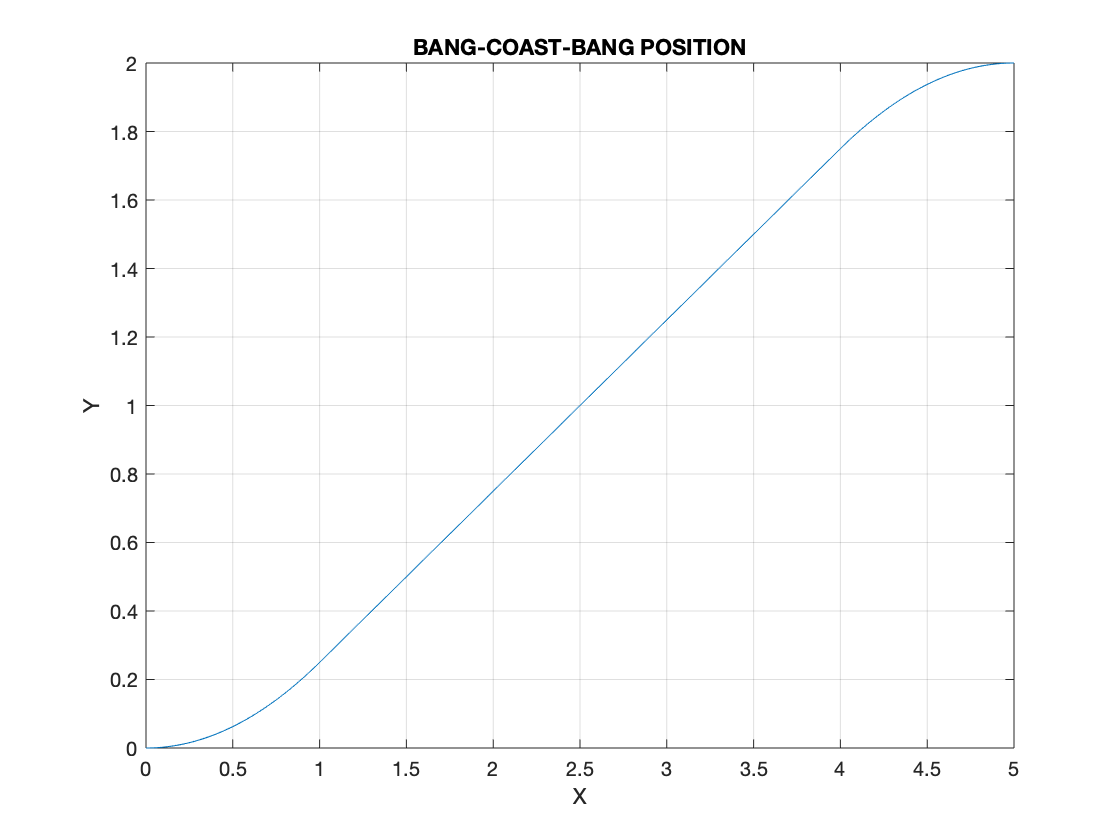

plot(time_vector,trapezoid_traj)
title('BANG-COAST-BANG POSITION')
xlabel('X');
ylabel('Y');
grid on

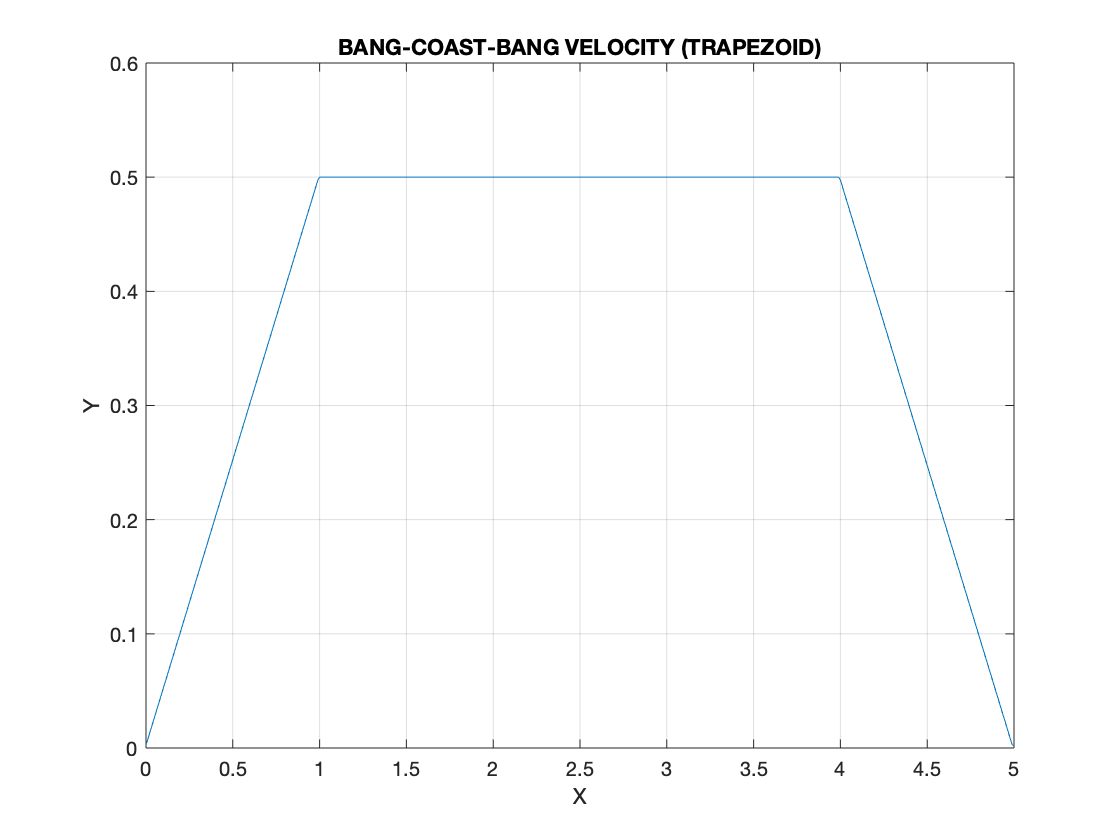


trapezoid_vel = time_vector;

% VELOCITY
for t=1:length(time_vector)-1
    trapezoid_vel(t) = (trapezoid_traj(t+1)-trapezoid_traj(t))/time_step;
end
trapezoid_vel(length(time_vector)) = trapezoid_vel(length(time_vector)-1);

plot(time_vector,trapezoid_vel)
title('BANG-COAST-BANG VELOCITY (TRAPEZOID)')
xlabel('X');
ylabel('Y');
grid on

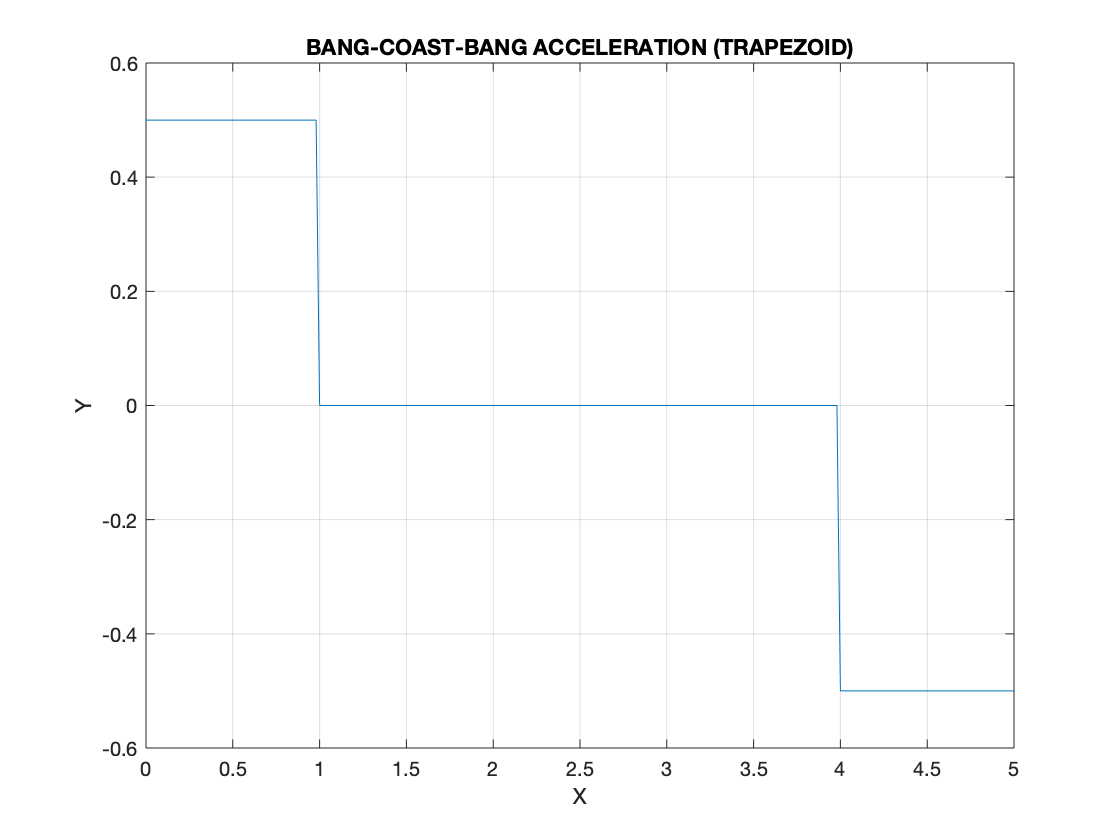


trapezoid_acc = time_vector;

% ACCELERATION
for t=1:length(time_vector)-2
    trapezoid_acc(t) = (trapezoid_vel(t+1)-trapezoid_vel(t))/time_step;
end
trapezoid_acc(length(time_vector)-1) = trapezoid_acc(length(time_vector)-2);
trapezoid_acc(length(time_vector)) = trapezoid_acc(length(time_vector)-1);

plot(time_vector,trapezoid_acc)
title('BANG-COAST-BANG ACCELERATION (TRAPEZOID)')
xlabel('X');
ylabel('Y');
grid on

# OVER-FLY

# 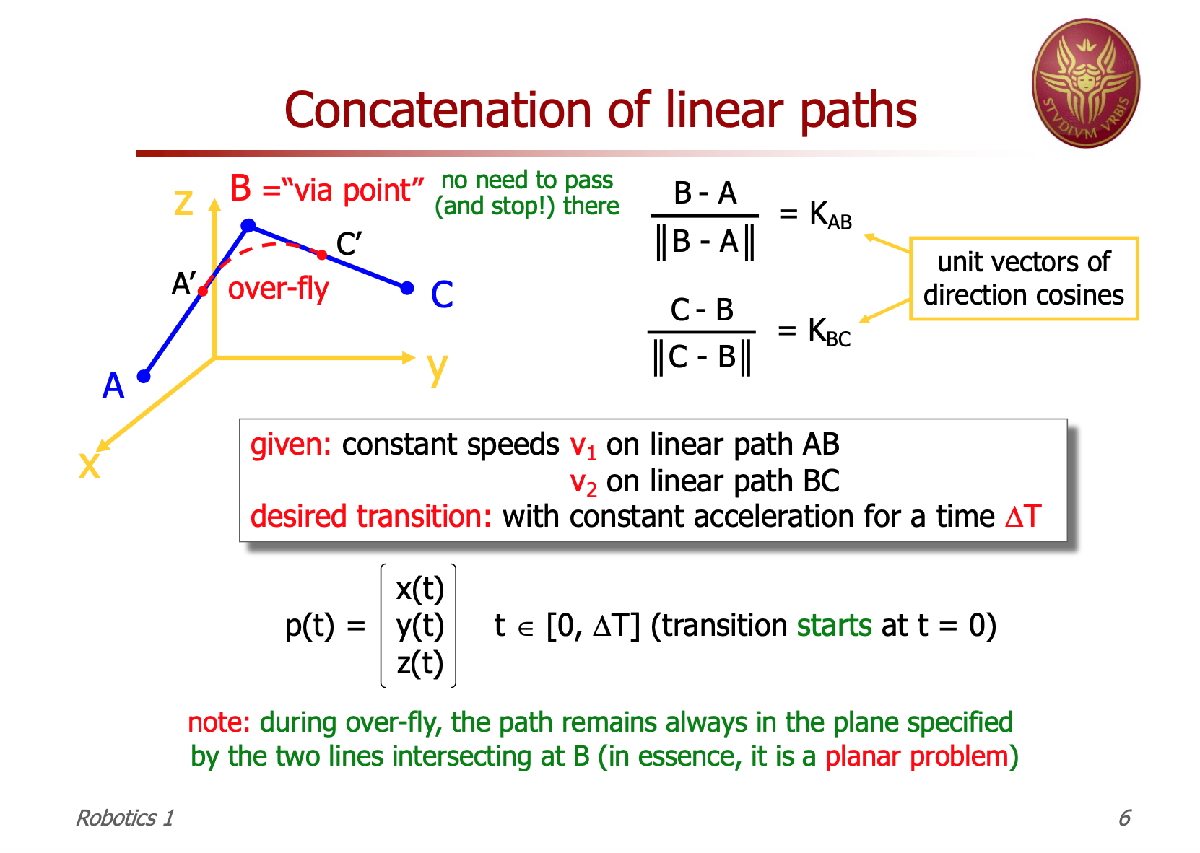

% IMPORTANT: resulting path are the same but scaled over time.
% PATH: parabolic
% VELOCITY: linear
% ACCELERATION: constant in DT
% can plot timing law for each component

start_time=0;
end_time=4;
T = end_time-start_time;

time_step=0.01;
num_steps=T/time_step;
time_vector = time_step * [start_time:num_steps]';

[A, B, C] = deal([3 3 0]', [1 9 4]', [8 9 8]');
[v1,v2] = deal(1,2);
% can specify one of the following conditions {d1,d2,DT,a_max}

over_fly_traj = [zeros(length(time_vector),3)];

% TRAJECTORY
for t=1:length(time_vector)
    [over_fly_traj(t,:),DT] = SR_ROBO.over_fly(A,B,C,v1,v2,time_vector(t),'DT',T);
end

clf;
disp('TIME INTERVAL CONDITION OVERFLY')

TIME INTERVAL CONDITION OVERFLY


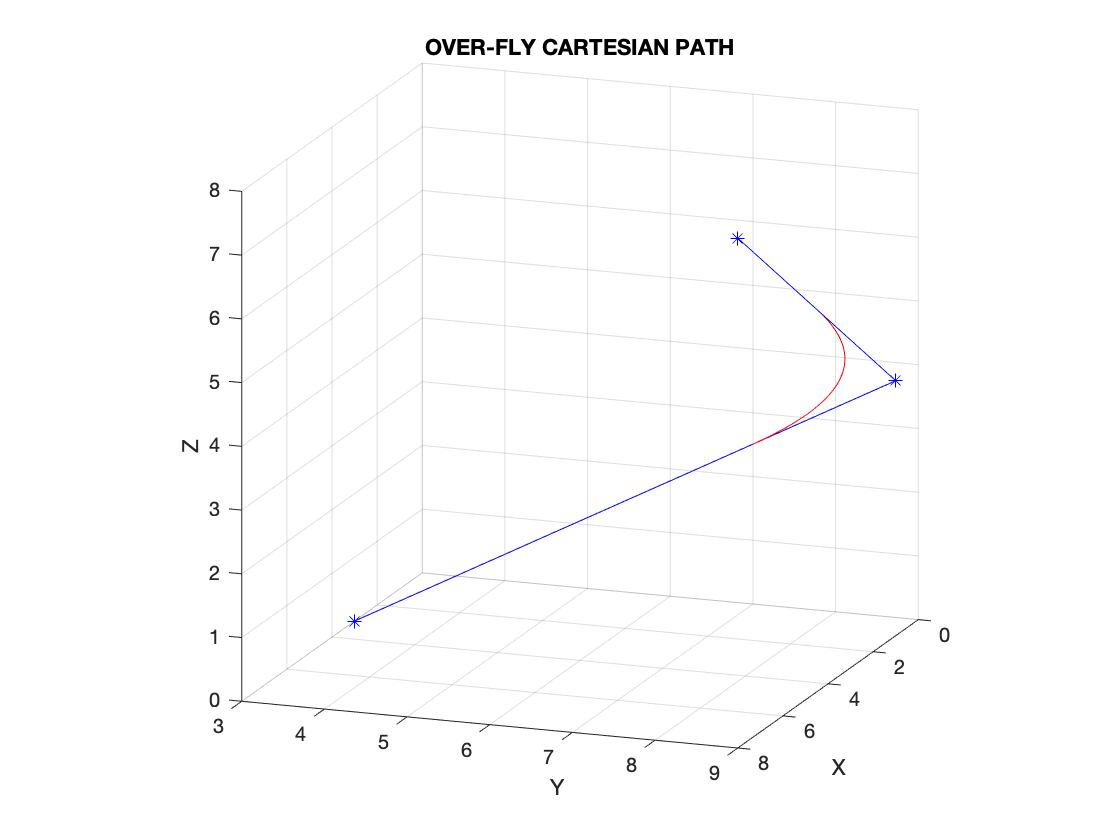

hold on
plot3(over_fly_traj(:,1),over_fly_traj(:,2),over_fly_traj(:,3), 'r')
plot3([A(1),B(1),C(1)]',[A(2),B(2),C(2)]',[A(3),B(3),C(3)]', 'b-*')
title('OVER-FLY CARTESIAN PATH')
xlabel('X');
ylabel('Y');
zlabel('Z');
view([110 15]);
grid on
pbaspect([1 1 1]);
hold off

[A, B, C] = deal([3 3 0]', [1 9 4]', [8 9 8]');
[v1,v2] = deal(1,2);
% can specify one of the following conditions {d1,d2,DT,a_max}

[~,T] = SR_ROBO.over_fly(A,B,C,v1,v2,0,'d1',3); % rememeber to change value also in foor loop

time_step=0.01;
num_steps=T/time_step;
time_vector = time_step * [start_time:num_steps]';

over_fly_traj = [zeros(length(time_vector),3)];

% TRAJECTORY
for t=1:length(time_vector)
    [over_fly_traj(t,:),DT] = SR_ROBO.over_fly(A,B,C,v1,v2,time_vector(t),'d1',3);
end

clf;
disp('PARAMETERS {d1,d2,DT,a_max} CONDITION OVERFLY')

PARAMETERS {d1,d2,DT,a_max} CONDITION OVERFLY


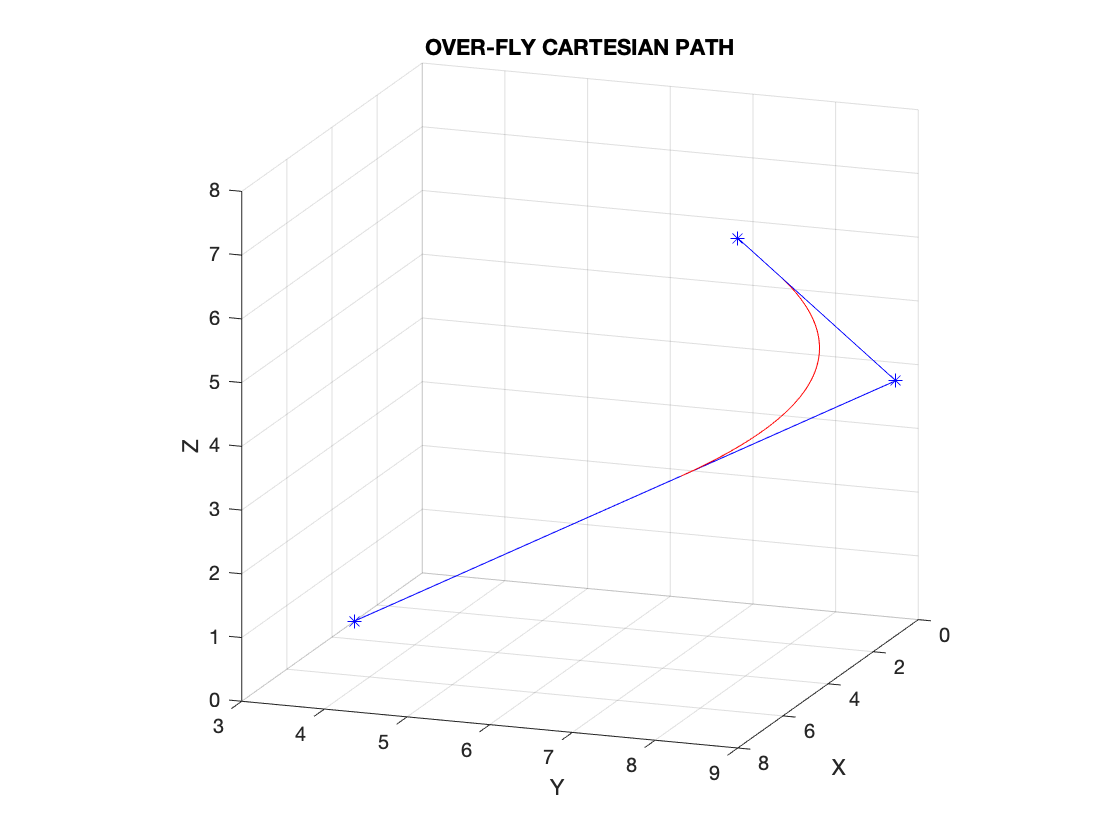

hold on
plot3(over_fly_traj(:,1),over_fly_traj(:,2),over_fly_traj(:,3), 'r')
plot3([A(1),B(1),C(1)]',[A(2),B(2),C(2)]',[A(3),B(3),C(3)]', 'b-*')
title('OVER-FLY CARTESIAN PATH')
xlabel('X');
ylabel('Y');
zlabel('Z');
view([110 15]);
grid on
pbaspect([1 1 1]);
hold off

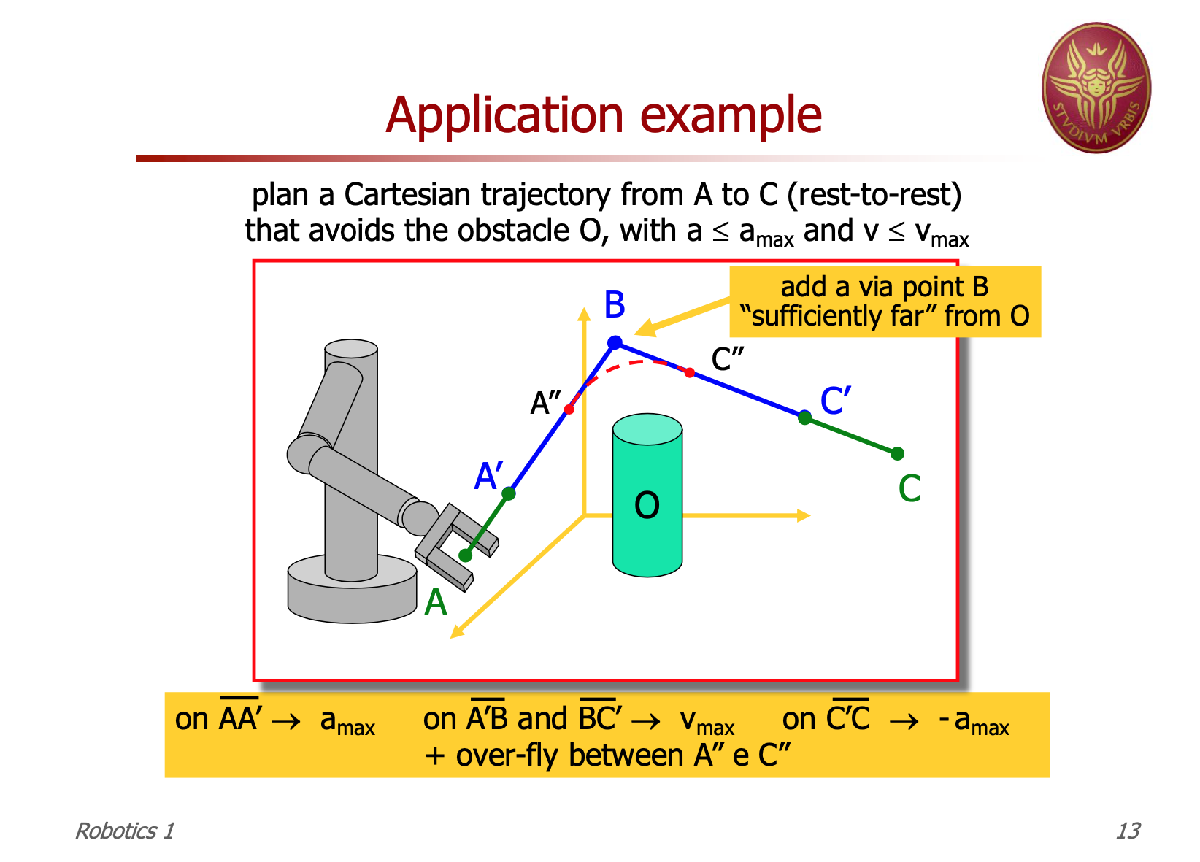

# CIRCULAR PATH GIVEN 3 POINTS

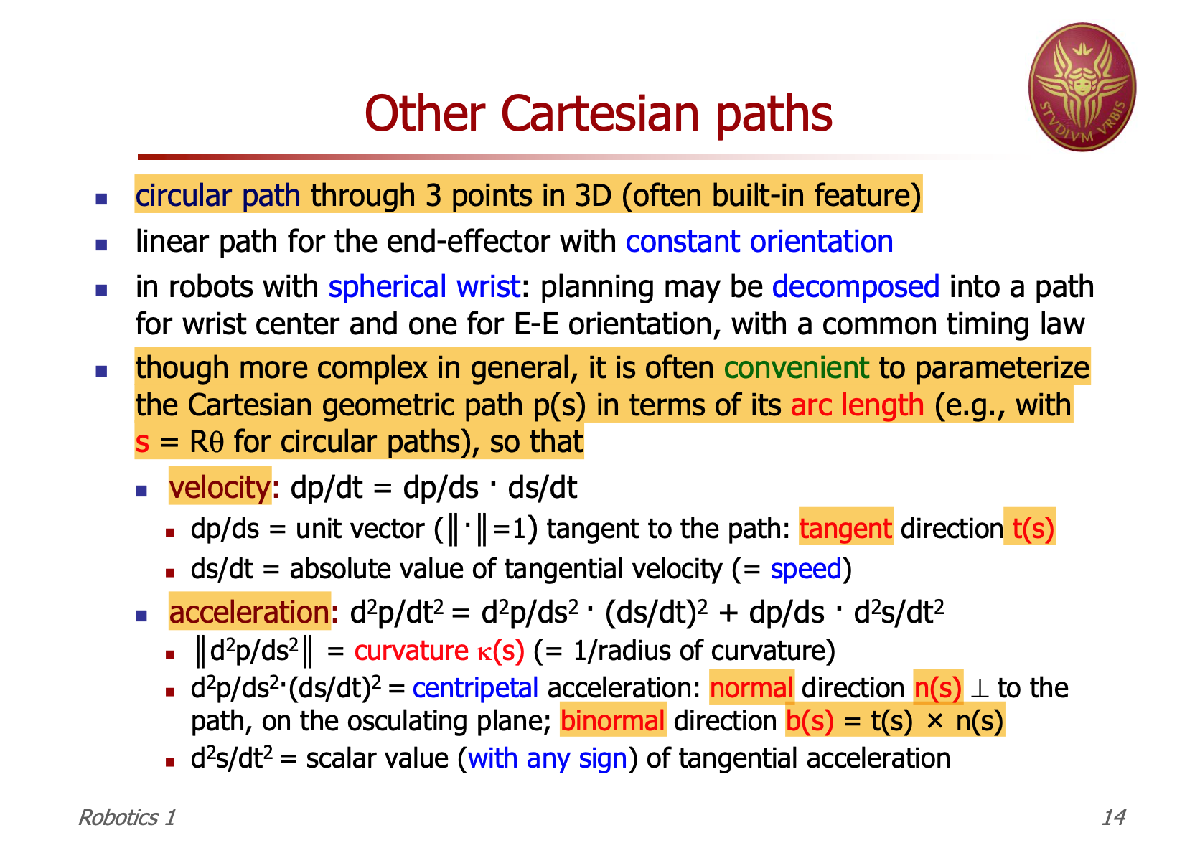

[A, B, C] = deal([3 3 0]', [1 9 4]', [8 9 8]');
[~,c,r] = SR_ROBO.circular_3_points(A,B,C,0)

c =     5.6485
    5.8894
    3.9901


r = 5.5932


start_time=0;
end_time=1;
T = end_time-start_time;

time_step=0.01;
num_steps=T/time_step;
time_vector = time_step * [start_time:num_steps]';

% can specify one of the following conditions {d1,d2,DT,a_max}
% remember last point equal to first
circular_traj = [zeros(length(time_vector),3)];

% TRAJECTORY
for t=1:length(time_vector)
    [circular_traj(t,:),~,~] = SR_ROBO.circular_3_points(A,B,C,time_vector(t));
end

clf;
disp('CIRCULAR PATH GIVEN 3 POINTS')

CIRCULAR PATH GIVEN 3 POINTS


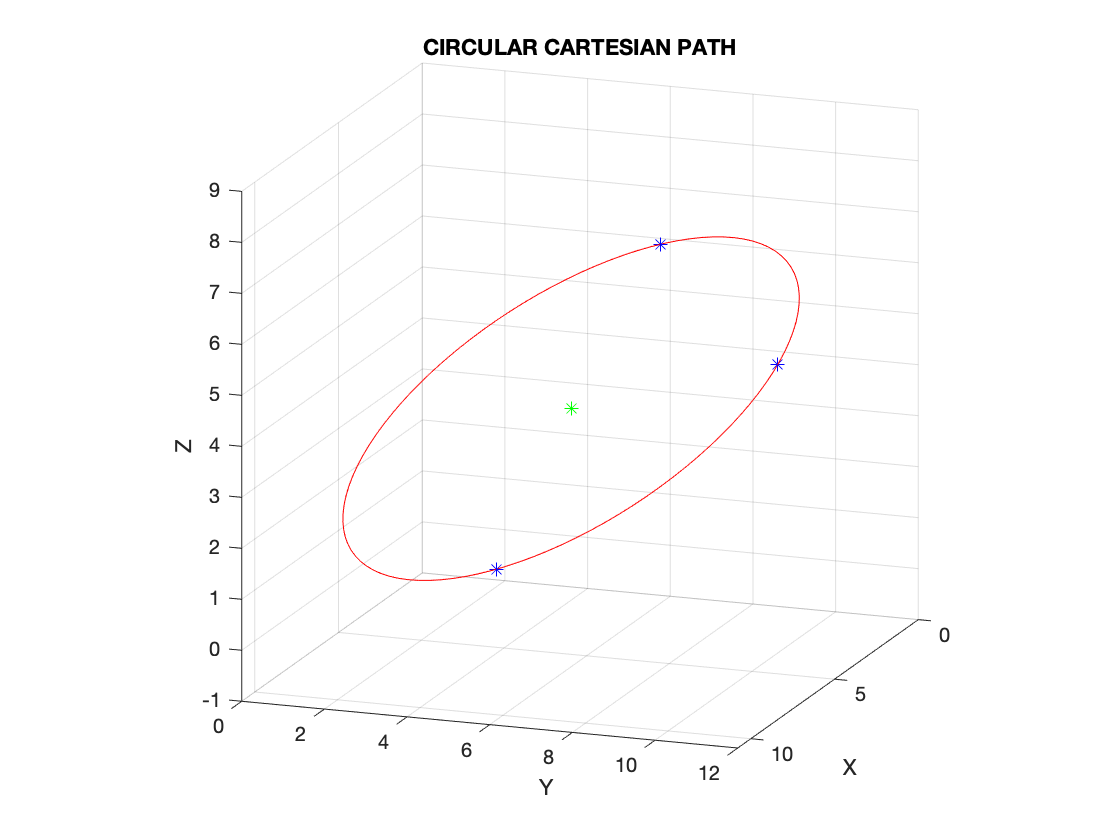

hold on
plot3(circular_traj(:,1),circular_traj(:,2),circular_traj(:,3), 'r')
plot3([A(1),B(1),C(1)]',[A(2),B(2),C(2)]',[A(3),B(3),C(3)]', 'b*')
plot3(c(1),c(2),c(3), 'g*')

title('CIRCULAR CARTESIAN PATH')
xlabel('X');
ylabel('Y');
zlabel('Z');
view([110 15]);
grid on
pbaspect([1 1 1]);
hold off

# FRENET FRAME

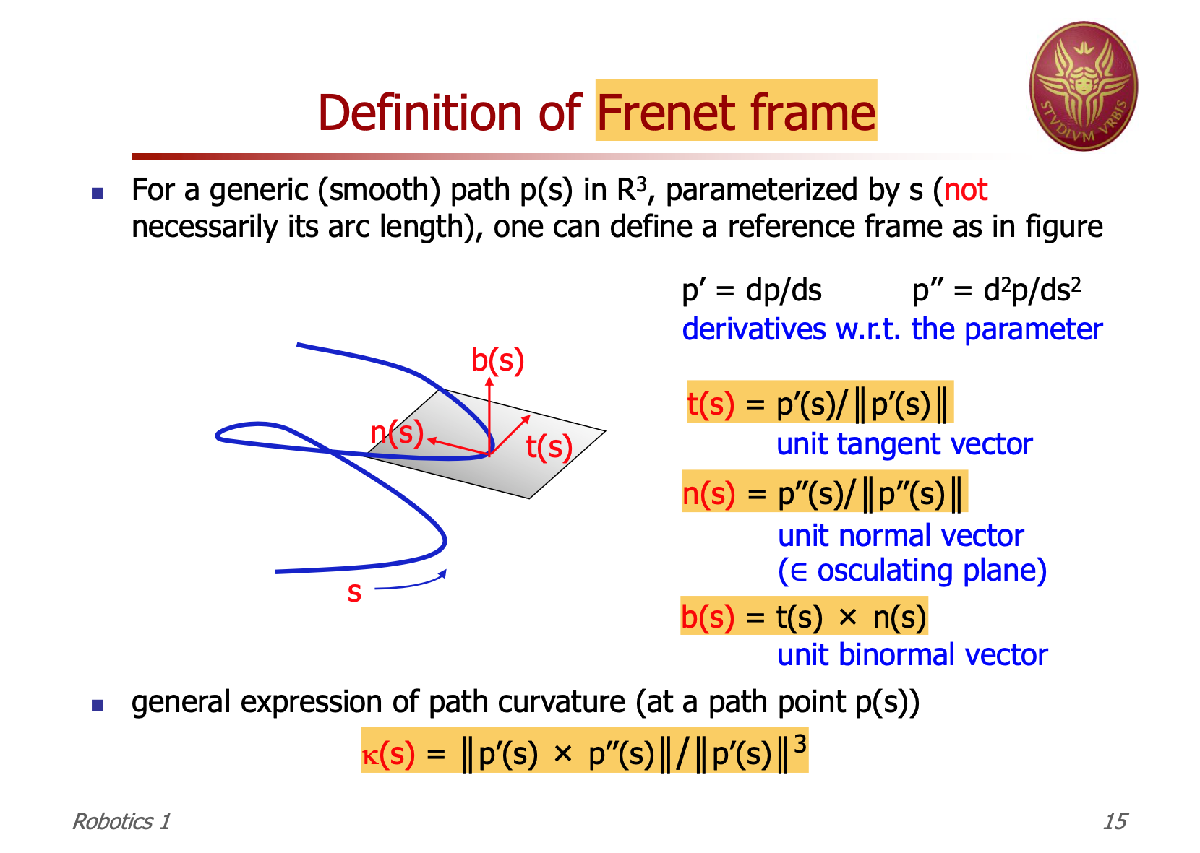

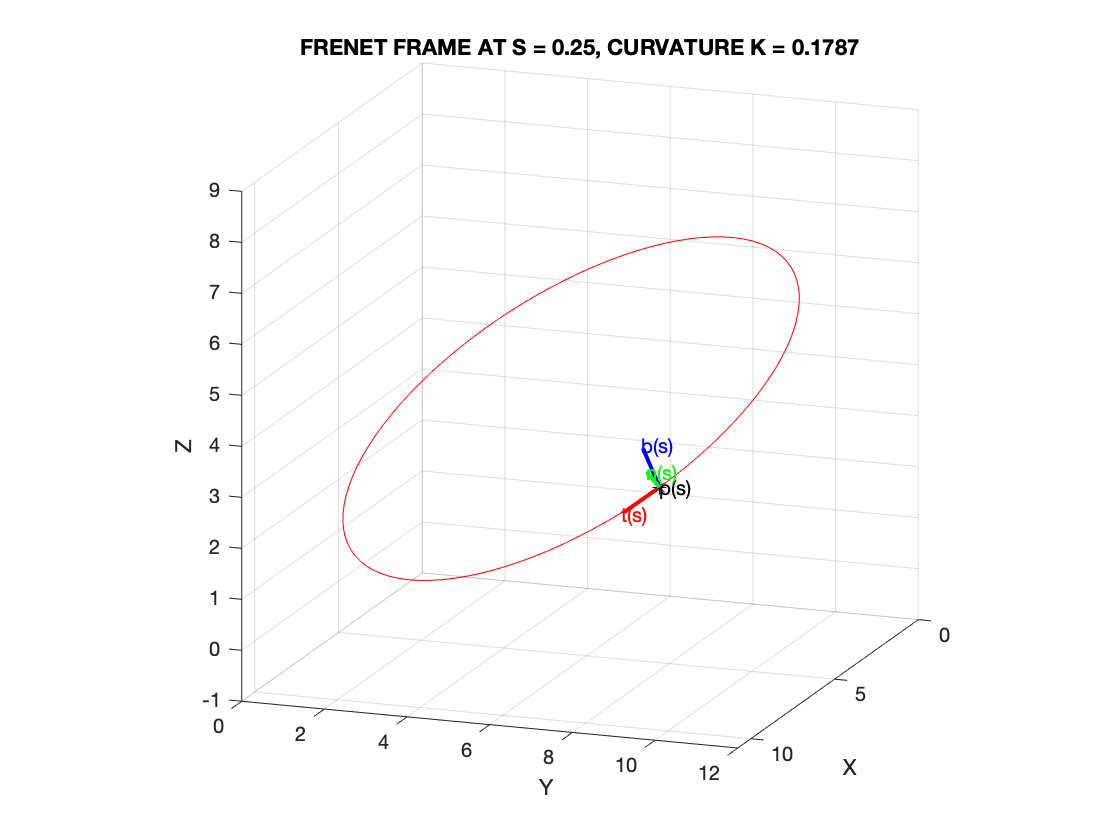

% p timing law (trajectory)
s = 0.25;

[t,n,b,k,p_s]= SR_ROBO.frenet(circular_traj,s);

SR_ROBO.draw_frenet(circular_traj,s);

# AXIS ANGLE ORIENTATION TRAJECTORY

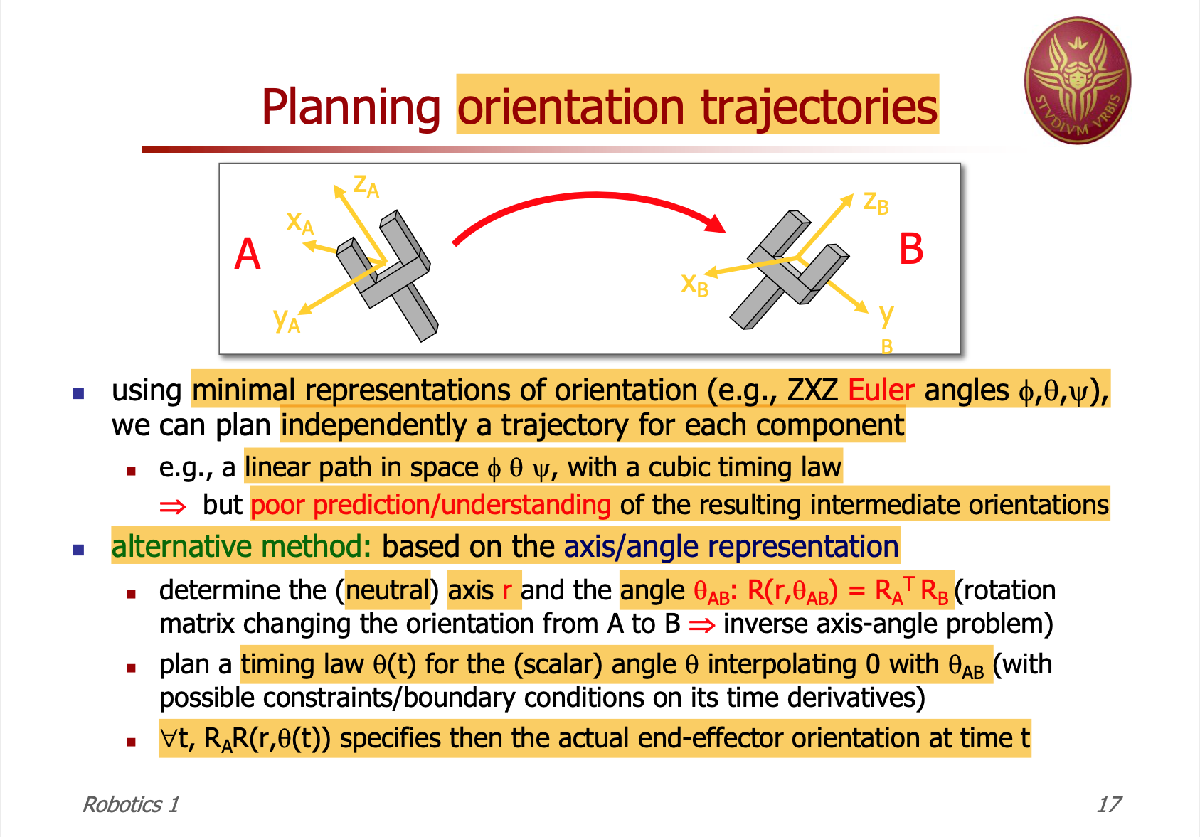

R_a = [0 0 1;
    0 -1 0;
    1 0 0];
R_b = [1 0 0;
    0 0 1;
    0 -1 0];

[R_theta_s,r,theta_ab] = SR_ROBO.axis_angle_trajectory(R_a,R_b,0)

R_theta_s =      0     0     1
     0    -1     0
     1     0     0


r = 0

theta_ab =     0.5774
   -0.5774
    0.5774



start_time=0;
end_time=1;
T = end_time-start_time;

time_step=0.01;
num_steps=T/time_step;
time_vector = time_step * [start_time:num_steps]';

% can specify one of the following conditions {d1,d2,DT,a_max}
% remember last point equal to first (remove ; in library to check it)
roration_traj = zeros(3,3,length(time_vector));
theta_traj = zeros(length(time_vector),1);
% NOTICE: for bcb animation seems to flow fine but time
% instead is reduced of a lot

% when use knots, first and last position is 
% modified according to [0, \theta_ab] task. 
% velocity can be imposed.
% knots = {{0, 0, 0 * T}, ...
%     {0.3, 0, 'none'}, ... % fake knots
%     {0.4, 2*pi, 'none'}, ... # intermediate knots whatever velocity
%     {0.6, pi/2, 'none'}, ...
%     {0.7, 0, 'none'}, ... % fake knots
%     {1, pi, 0 * T}};
% insert as last arguments -->  'cubic_spline','knots',knots

% TRAJECTORY
for t=1:length(time_vector)
    [roration_traj(:,:,t),theta_s,~,~] = SR_ROBO.axis_angle_trajectory(R_a,R_b,time_vector(t),'bcb','v_max',pi/4,'a_max',pi/8);
    theta_traj(t)=theta_s;
end

Real T = 4.666667

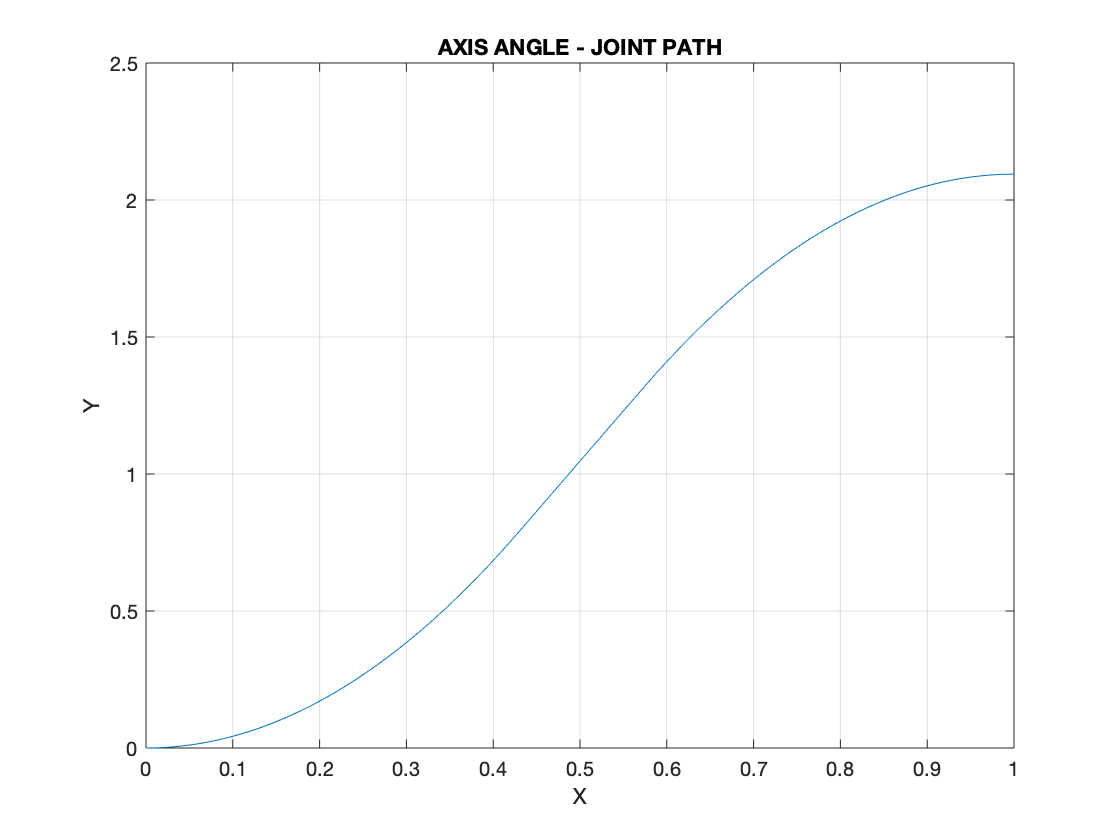


plot(time_vector,theta_traj)
title('AXIS ANGLE - JOINT PATH')
xlabel('X');
ylabel('Y');
grid on

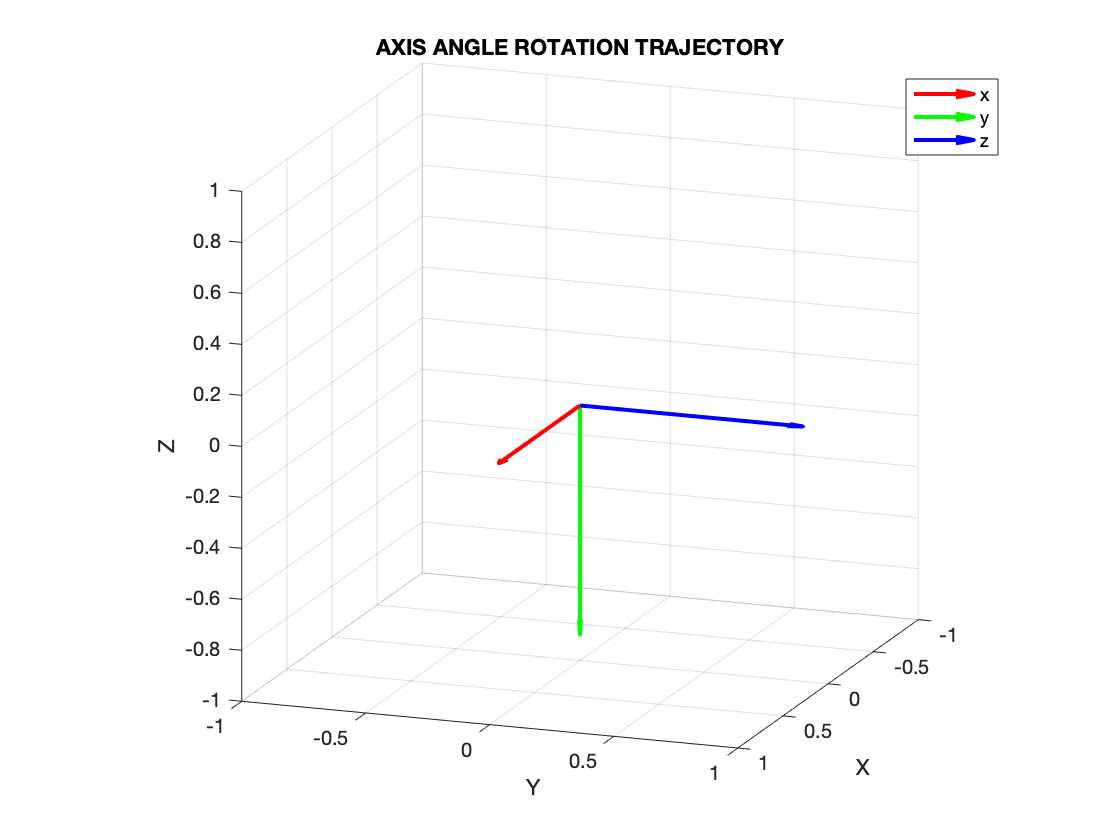


SR_ROBO.draw_axis_angle_trajectory(roration_traj);

# TIME SCALING